# Exercise 2: Setup Estimation Filter to Track A Single Piece of Space Debris

## **A. Load Data**

First, let's test how the default constant velocity extended kalman filter performs on our dataset for a single piece of space debris.

We can clear our workspace and command window and also close all open figures with the commands below:

clear; clc; close all; addpath('../HelperFunctions/')

Let's load in our truth and detection data from the previous example:

S = load('SpaceDebrisLEO_1Target.mat');
truthPosition = S.truthPos;       % Truth Position - where the target actually is
detectionPosition = S.detPos;     % Detection Position - where the target was detected
time = S.time;                    % Time vector, maps to each detection
objectDetection = S.objDet;       % Object Detection as an "object detection object"
speed = S.speed;                  % Known speed of debris
initialDetection = objectDetection{1}; % Object Detection format of detection
detectionMeasurementNoise = initialDetection.MeasurementNoise; % Measurment Noise associated with detections

## **B. Define and Run Filter on Detections**

Coding Directions:

1) Please create a variable 'filter' that holds the default Constant Velocity Extended Kalman Filter (EKF) estimation filter. Define the estimation filter using a "initcvekf" filter. This filter initialization function requires a detection as input. Pass the "initialDetection" to "initcvekf".

2) Consider Adjusting parameters of filter within "initFilter", such as:

            `knownVelo = 7.5e3; % m/s - Estimate of Space Debris Velocity`

            `initialStateCovariance = blkdiag(detectionMeasurementNoise(1)^2,knownVelo^2,...`

            `    detectionMeasurementNoise(1)^2,knownVelo^2,...`

            `    detectionMeasurementNoise(1)^2,knownVelo^2);`

            `processNoise = blkdiag(1,1,1)*10^3;`

            `filter.StateCovariance = initialStateCovariance;`

            `filter.ProcessNoise = processNoise;`

`3) `Consider using an unscented kalman filter. Accomplished by changing the filter initialization function from "initcvekf" to "initcvukf"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc initcvekf" in the Command Window to find the documentation page for this function
filter = initFilter(initialDetection);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function filter = initFilter(detection)
filter = initcvekf(detection); % <----- 3) Adjust filter type

% 2) Adjust Filter Parameters
% Without changing parameters below, this filter runs with default inputs
% filter.StateCovariance = 
% filter.ProcessNoise = 

end

### **Plot Detections, Predictions, and Corrections**

Loop through the detection data and run filter as the target moves through the space.

display = createDisplay(truthPosition)

Unable to use a value of type struct as an index.

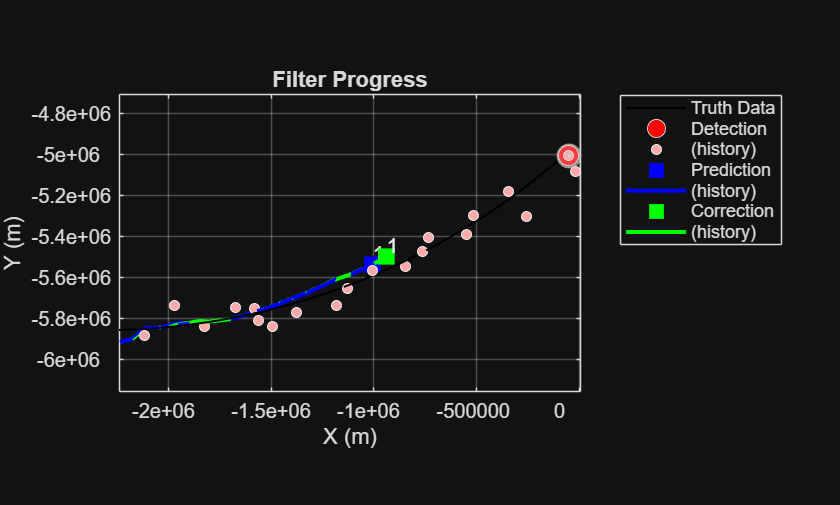

for n = 2:length(time)
    deltaT = time(n)-time(n-1);

    % Predict
    predict(filter,deltaT);

    % Update Display - predicted state
    updateDisplay(display,filter,detectionPosition(:,n)',detectionMeasurementNoise,1,truthPosition(:,n));
    
    filter.MeasurementNoise = detectionMeasurementNoise;

    % Log the Distance Value -> dn = r'/S*r + log(|S|)
    logDist(n) = distance(filter, detectionPosition(:,n));

    % Correct
    correct(filter, detectionPosition(:,n));
    
    % Update Display - corrected state
    updateDisplay(display,filter,detectionPosition(:,n)',detectionMeasurementNoise,2,truthPosition(:,n));
    
end

If you are interested in distance calculation, see Algorithm Definition here: 

[distance](https://www.mathworks.com/help/fusion/ref/trackingekf.distance.html?s_tid=srchtitle_support_results_4_distance)

## **C. Evaluate Metrics**

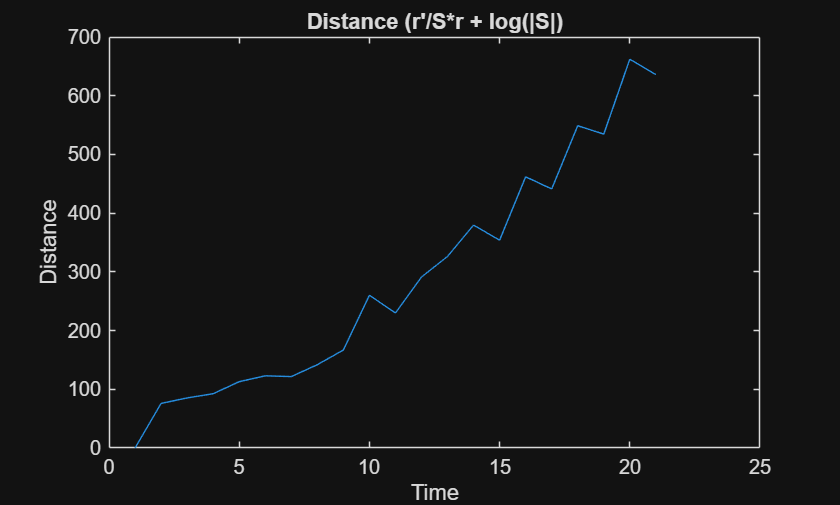

figure; plot(logDist); title('Distance (r''/S*r + log(|S|)'); xlabel('Time'); ylabel('Distance')

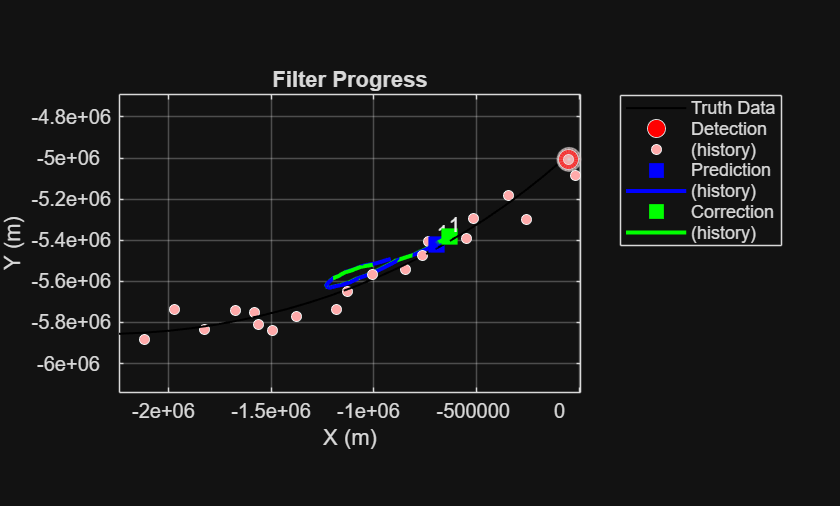

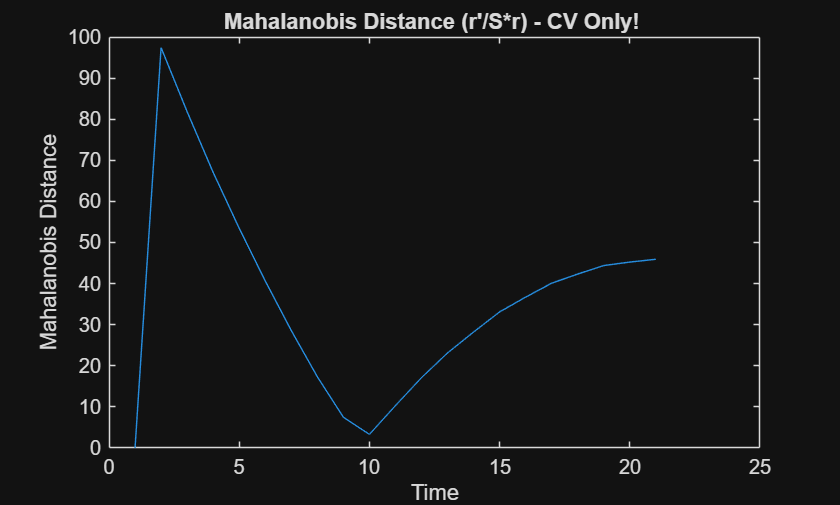

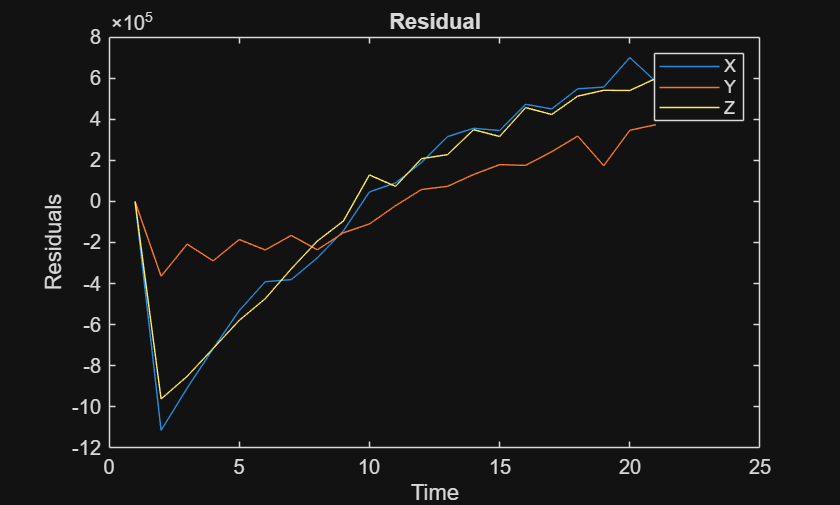

runFilterCollectMetrics(filter,truthPosition,detectionPosition,detectionMeasurementNoise,time)

# **Takeaways**

- Exercised the utility and compatibility of the filter initialization functions

- Tuned the filter to apply to space debris data

- Evaluated filter accuracy through metrics - distance, mahalanobis distance, and residual

**BONUS - Tune Filter Using "tuneFilter" Function**

I have setup the trackingFilterTuner for you. If you are interesting in how this was done, please check the Live Script "TuneFilter_CV.mlx" in the Soluions folder.

**createDisplay**

function display = createDisplay(truthPosition)
% This function creates the display for visualizing tracks, detections, and
% ground truth. 

display.tp = theaterPlot();

% Create Plotters
display.trajPlotter = trajectoryPlotter(display.tp,'DisplayName','Truth Data','LineWidth',1,'LineStyle','-','Color','k');
display.detPlotter = detectionPlotter(display.tp,'HistoryDepth',1e3,'DisplayName','Detection','MarkerSize',10,'MarkerFaceColor','r');
display.predPlotter = trackPlotter(display.tp,'HistoryDepth',1e3,'DisplayName','Prediction','MarkerSize',10,'MarkerFaceColor','b','MarkerEdgeColor','b','ConnectHistory','on');
display.corrPlotter = trackPlotter(display.tp,'HistoryDepth',1e3,'DisplayName','Correction','MarkerSize',10,'MarkerFaceColor','g','MarkerEdgeColor','g','ConnectHistory','on');

% Plot Truth As Trajectory
plotTrajectory(display.trajPlotter,{truthPosition'})
grid on, box on; legend(gca,'Location','northwest')

% Add Title and Rotate to 2D view
title('Filter Progress'); hold on; grid on; axis equal; % Add Title
view([0 90.00]) % Rotate to 2D view

end

**updateDisplay**

function [mahalanobisDist,zres,rescov] = updateDisplay(display,filter,detectionPosition,detectionMeasurementNoise,plotFlag,truthPosition)
% This function updates the display for plotting ground truth, detections,
% and tracks. 

% Plot Position of Current Detection iteration 
plotDetection(display.detPlotter,detectionPosition,detectionMeasurementNoise) % Adds ellipses on Detections

% Collect filter position and position covariance estimates
stateStruct = struct('State',filter.State,'StateCovariance',filter.StateCovariance);
[positions, positionsCov] = getTrackPositions(stateStruct,'constvel');

% Plot Prediction or Correction
if plotFlag==1
    plotTrack(display.predPlotter,positions,positionsCov,string(1)) % Plot Prediction
elseif plotFlag==2
    plotTrack(display.corrPlotter,positions,positionsCov,string(1)) % Plot Correction
    
    % Calculate Mahalanobis Distance (CV only):
    e = positions' - truthPosition;
    P = positionsCov;
    mahalanobisDist = sqrt(e'/P*e);

    % Calculate the residual
    [zres, rescov] = residual(filter,detectionPosition);
else
    disp('Plot Flag Assigned incorrectly')
end


% Draw Detections and Tracks During Each Loop
drawnow

end

**runFilterCollectMetrics**

function runFilterCollectMetrics(filter,truthPosition,detectionPosition,detectionMeasurementNoise,time)

display = createDisplay(truthPosition);
for n = 2:length(time)
    deltaT = time(n)-time(n-1);

    % Predict
    predict(filter,deltaT);

    % Update Display - predicted state
    updateDisplay(display,filter,detectionPosition(:,n)',detectionMeasurementNoise,1)
    
    filter.MeasurementNoise = detectionMeasurementNoise;

    % Log the Distance Value -> dn = r'/S*r + log(|S|)
    logDist(n) = distance(filter, detectionPosition(:,n));

    % Correct
    correct(filter, detectionPosition(:,n));
    
    % Update Display - corrected state
    [mahalanobisDist(n),zres(:,n),rescov(:,:,n)] = updateDisplay(display,filter,detectionPosition(:,n)',detectionMeasurementNoise,2,truthPosition(:,n));
    
end

% Plot Mahalanobis
figure;
plot(mahalanobisDist)
title('Mahalanobis Distance (r''/S*r) - CV Only! '); xlabel('Time'); ylabel('Mahalanobis Distance')

% Plot Residual
figure;
plot(zres(1,:)); hold on;
plot(zres(2,:));
plot(zres(3,:));
title('Residual'); xlabel('Time'); ylabel('Residuals')
legend('X','Y','Z')


end